# Machine Learning Online Class

`Exercise 5 | Regularized Linear Regression and Bias-Variance`

`Instructions`

`------------`

`This file contains code that helps you get started on the`

`exercise. You will need to complete the following functions:`

`   linearRegCostFunction.m`

`   learningCurve.m`

`   validationCurve.m`

`For this exercise, you will not need to change any code in this file,`

`or any other files other than those mentioned above.`

## Initialization

clear ; close all; clc

## =========== Part 1: Loading and Visualizing Data =============

`We start the exercise by first loading and visualizing the dataset. `

`The following code will load the dataset into your environment and plot`

`the data.`

% Load Training Data
fprintf('Loading and Visualizing Data ...\n')

Loading and Visualizing Data ...


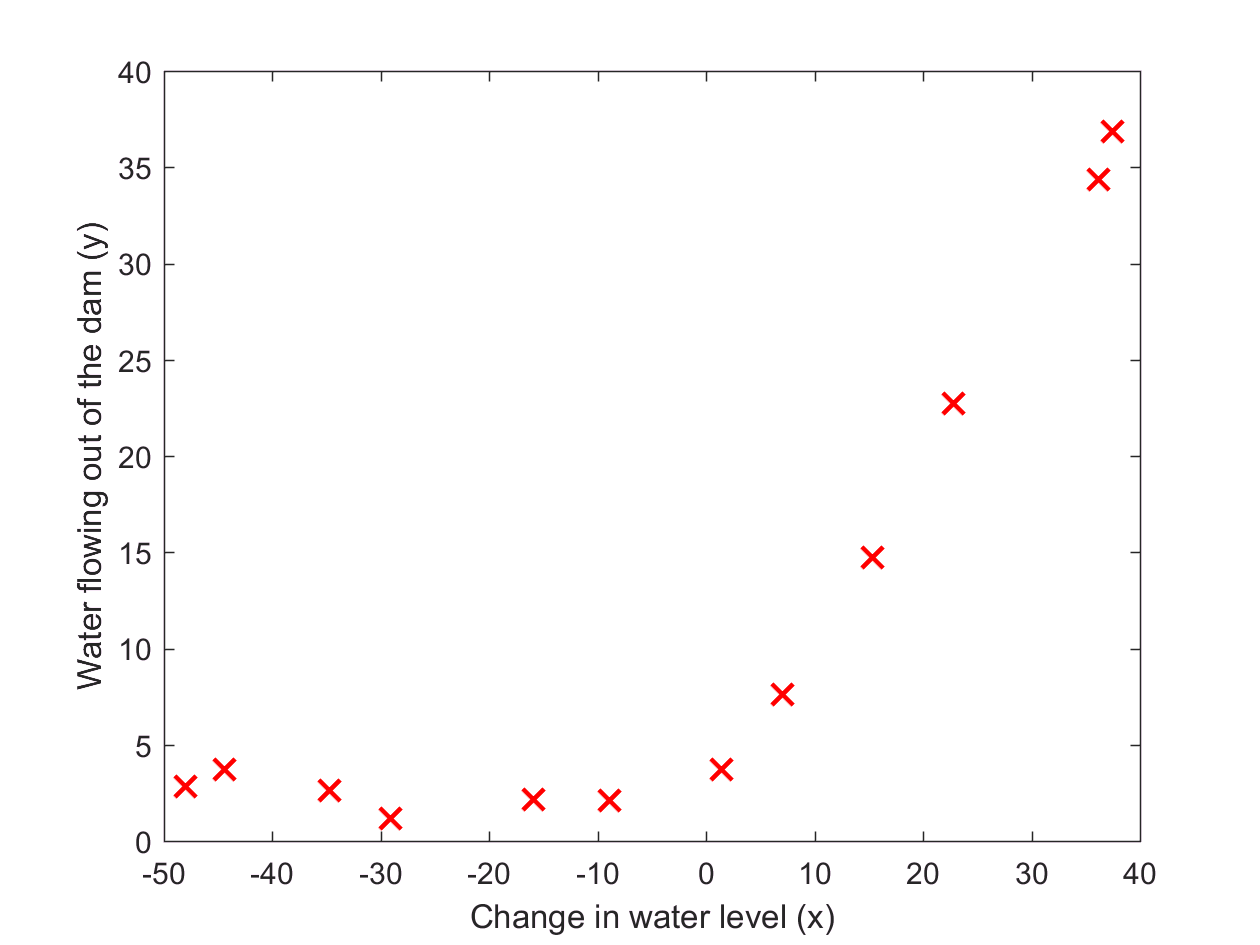


% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment
load ('ex5data1.mat');

% m = Number of examples
m = size(X, 1);

% Plot training data
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 2: Regularized Linear Regression Cost =============

`You should now implement the cost function for regularized linear `

`regression. `

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);

fprintf(['Cost at theta = [1 ; 1]: %f '...
         '\n(this value should be about 303.993192)\n'], J);

Cost at theta = [1 ; 1]: 303.993192 
(this value should be about 303.993192)



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 3: Regularized Linear Regression Gradient =============

`You should now implement the gradient for regularized linear `

`regression.`

theta = [1 ; 1];
[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);


fprintf(['Gradient at theta = [1 ; 1]:  [%f; %f] '...
         '\n(this value should be about [-15.303016; 598.250744])\n'], ...
         grad(1), grad(2));

Gradient at theta = [1 ; 1]:  [-15.303016; 598.250744] 
(this value should be about [-15.303016; 598.250744])



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 4: Train Linear Regression =============

`Once you have implemented the cost and gradient correctly, the`

`trainLinearReg function will use your cost function to train `

`regularized linear regression.`

`Write Up Note: The data is non-linear, so this will not give a great `

`               fit.`

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01


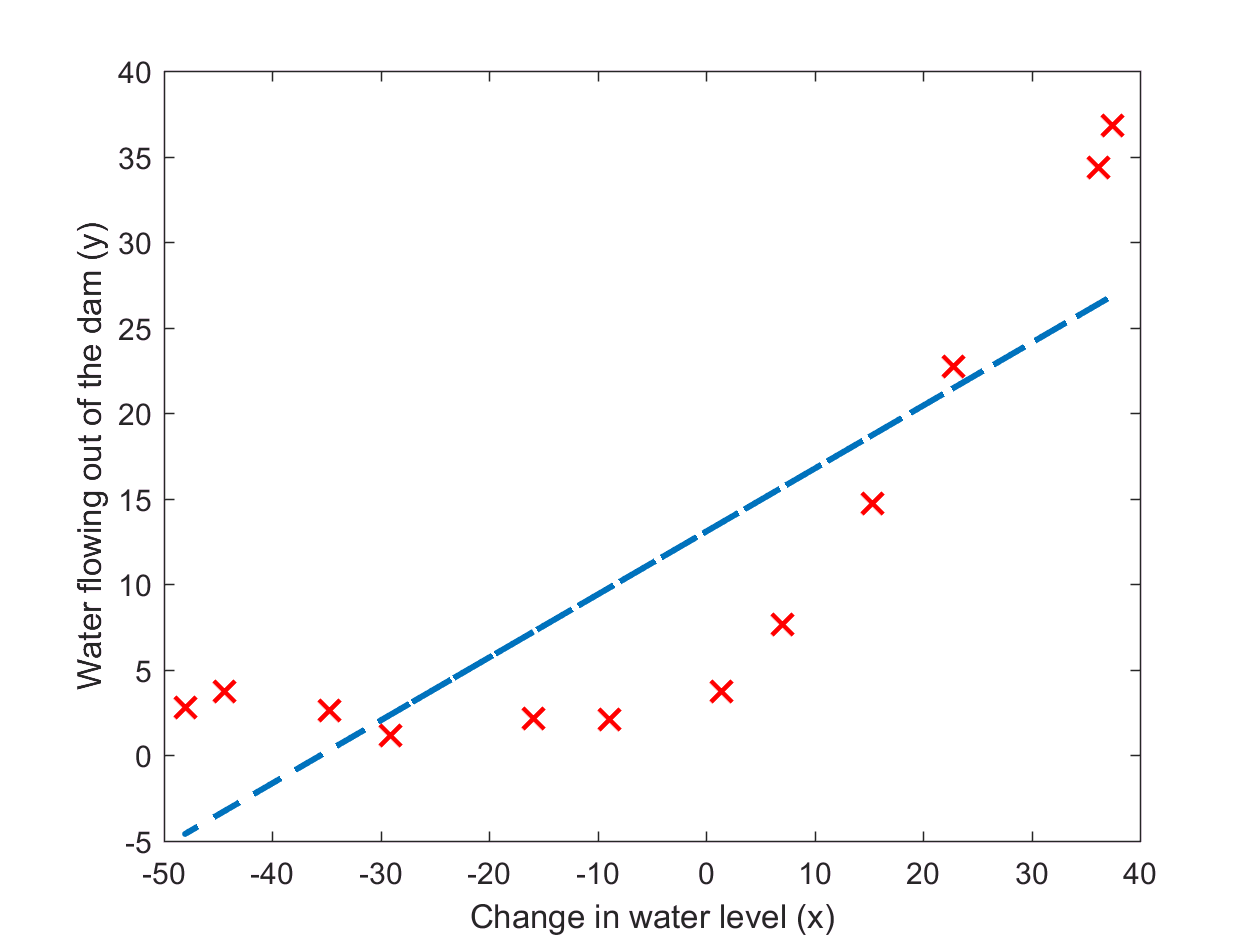


%  Plot fit over the data
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 5: Learning Curve for Linear Regression =============

`Next, you should implement the learningCurve function. `

`Write Up Note: Since the model is underfitting the data, we expect to`

`               see a graph with "high bias" -- Figure 3 in ex5.pdf `

lambda = 0;
[error_train, error_val] = ...
    learningCurve([ones(m, 1) X], y, ...-
                  [ones(size(Xval, 1), 1) Xval], yval, ...
                  lambda);

Iteration     1 | Cost: 9.738934e-01
Iteration     2 | Cost: 1.562805e-02
Iteration     3 | Cost: 4.400239e-04
Iteration     4 | Cost: 1.950388e-05
Iteration     5 | Cost: 8.007269e-07
Iteration     6 | Cost: 9.874376e-32
Iteration     8 | Cost: 7.829341e-36
Iteration     9 | Cost: 1.068251e-65
Iteration    10 | Cost: 3.692309e-67
Iteration    11 | Cost: 3.745341e-98
Iteration    12 | Cost: 7.386383e-127
Iteration    13 | Cost: 8.390633e-157
Iteration    14 | Cost: 1.359846e-184
Iteration    15 | Cost: 7.277616e-214
Iteration    16 | Cost: 6.748636e-243
Iteration    17 | Cost: 5.915261e-274
Iteration    18 | Cost: 1.511887e-301
Iteration    19 | Cost: 0.000000e+00
Iteration     1 | Cost: 2.832059e-05
Iteration     2 | Cost: 1.236973e-27
Iteration     3 | Cost: 2.465216e-28
Iteration     4 | Cost: 9.199666e-33
Iteration     1 | Cost: 9.738934e-01
Iteration     2 | Cost: 1.562805e-02
Iteration     3 | Cost: 4.400239e-04
Iteration     4 | Cost: 1.950388e-05
Iteration     5 | Cost: 8.00726

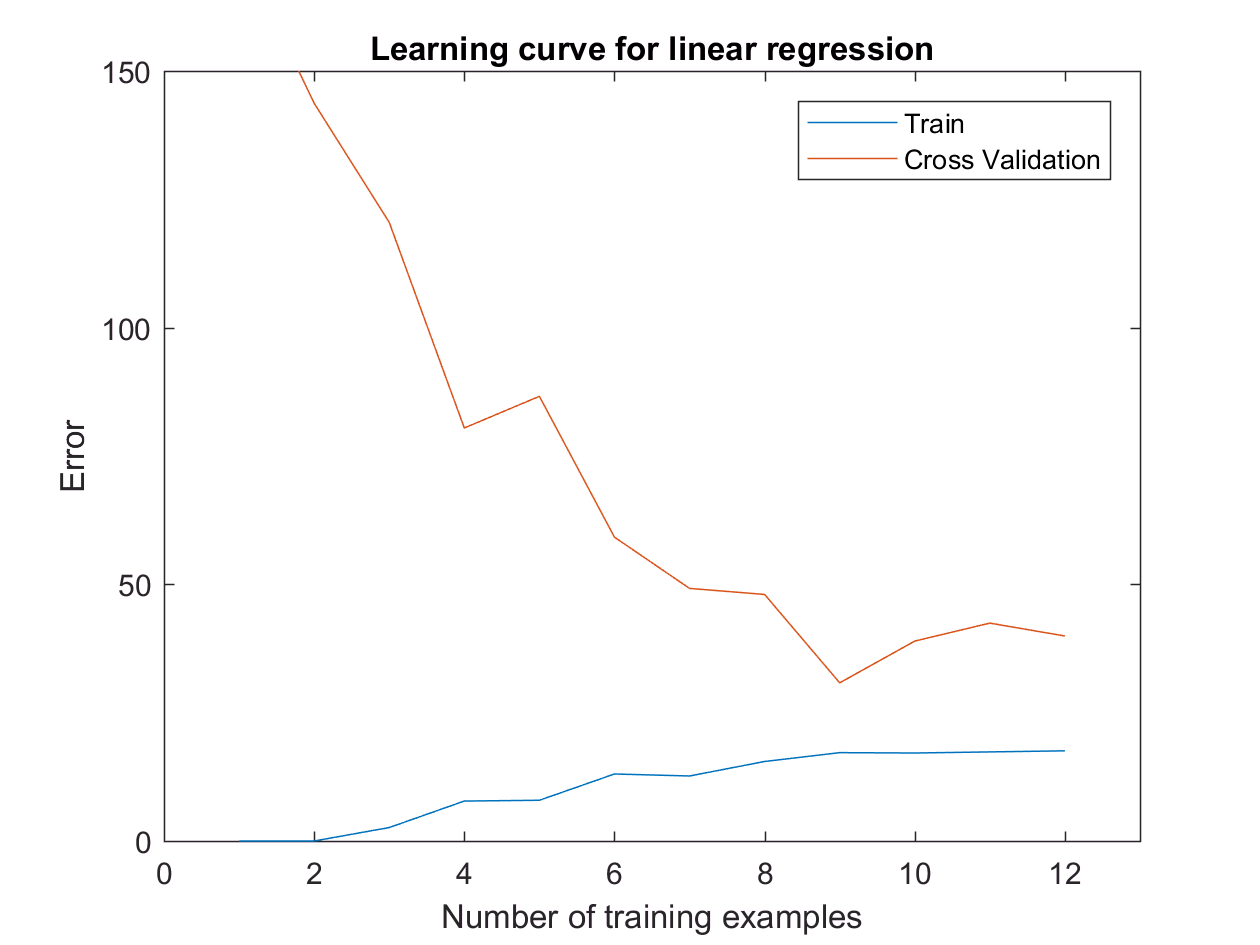


plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 150])


fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000000	174.264212


  	2		0.000002	143.722471


  	3		2.620890	120.510390


  	4		7.781195	80.458000


  	5		7.935794	86.628274


  	6		13.054839	59.187495


  	7		12.665099	49.208908


  	8		15.489851	48.028466


  	9		17.211381	30.811385


  	10		17.141474	38.945546


  	11		17.355590	42.443723


  	12		17.565755	39.934139



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 6: Feature Mapping for Polynomial Regression =============

`One solution to this is to use polynomial regression. You should now`

`complete polyFeatures to map each example into its powers`

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = bsxfun(@minus, X_poly_test, mu);
X_poly_test = bsxfun(@rdivide, X_poly_test, sigma);
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = bsxfun(@minus, X_poly_val, mu);
X_poly_val = bsxfun(@rdivide, X_poly_val, sigma);
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');

Normalized Training Example 1:


fprintf('  %f  \n', X_poly(1, :));

  1.000000  
  -0.362141  
  -0.755087  
  0.182226  
  -0.706190  
  0.306618  
  -0.590878  
  0.344516  
  -0.508481  



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## =========== Part 7: Learning Curve for Polynomial Regression =============

`Now, you will get to experiment with polynomial regression with multiple`

`values of lambda. The code below runs polynomial regression with `

`lambda = 0. You should try running the code with different values of`

`lambda to see how the fit and learning curve change.`

lambda = 0.01;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.273556e+01
Iteration     2 | Cost: 2.689698e+01
Iteration     3 | Cost: 1.330795e+01
Iteration     4 | Cost: 3.522725e+00
Iteration     5 | Cost: 2.931455e+00
Iteration     6 | Cost: 2.460864e+00
Iteration     7 | Cost: 2.422567e+00
Iteration     8 | Cost: 1.963935e+00
Iteration     9 | Cost: 1.844362e+00
Iteration    10 | Cost: 1.347999e+00
Iteration    11 | Cost: 9.926163e-01
Iteration    12 | Cost: 7.288198e-01
Iteration    13 | Cost: 6.328946e-01
Iteration    14 | Cost: 5.670065e-01
Iteration    15 | Cost: 5.639823e-01
Iteration    16 | Cost: 5.548234e-01
Iteration    17 | Cost: 5.499414e-01
Iteration    18 | Cost: 5.494877e-01
Iteration    19 | Cost: 5.424332e-01
Iteration    20 | Cost: 5.361573e-01
Iteration    21 | Cost: 5.315018e-01
Iteration    22 | Cost: 5.275814e-01
Iteration    23 | Cost: 5.217942e-01
Iteration    24 | Cost: 5.202317e-01
Iteration    25 | Cost: 5.134932e-01
Iteration    26 | Cost: 5.118634e-01
Iteration    27 | Cost: 4.994810e-01
I

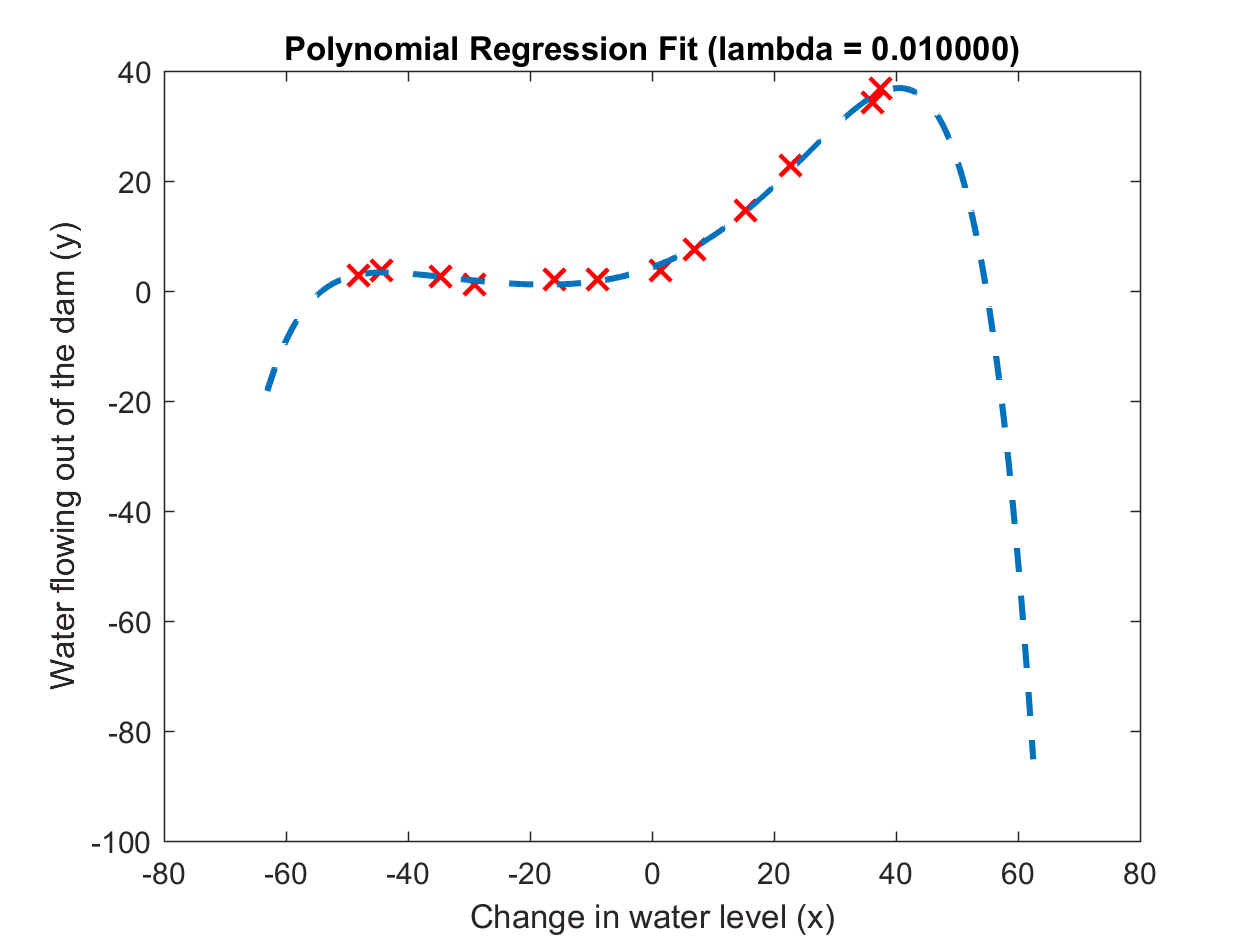


% Plot training data and fit
figure(1);
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));


figure(2);
[error_train, error_val] = ...
    learningCurve(X_poly, y, X_poly_val, yval, lambda);

Iteration     1 | Cost: 8.861557e-01
Iteration     2 | Cost: 3.858909e-03
Iteration     3 | Cost: 1.919122e-04
Iteration     4 | Cost: 1.620714e-04
Iteration     5 | Cost: 1.475633e-04
Iteration     6 | Cost: 1.360899e-05
Iteration     7 | Cost: 1.434571e-07
Iteration     8 | Cost: 1.127401e-09
Iteration     9 | Cost: 7.766055e-11
Iteration    10 | Cost: 2.352620e-11
Iteration    11 | Cost: 5.795267e-13
Iteration    12 | Cost: 5.484401e-13
Iteration    13 | Cost: 5.100991e-13
Iteration    14 | Cost: 5.097647e-13
Iteration    15 | Cost: 1.139414e-25
Iteration    16 | Cost: 1.742784e-26
Iteration    17 | Cost: 3.856384e-27
Iteration    18 | Cost: 1.804765e-27
Iteration    19 | Cost: 6.029779e-28
Iteration    20 | Cost: 1.856897e-28
Iteration    21 | Cost: 6.196392e-29
Iteration    22 | Cost: 2.981033e-29
Iteration    23 | Cost: 2.030485e-29
Iteration    24 | Cost: 2.035317e-30
Iteration    25 | Cost: 5.215669e-31
Iteration    26 | Cost: 2.445890e-31
Iteration    27 | Cost: 9.980654e-32
I

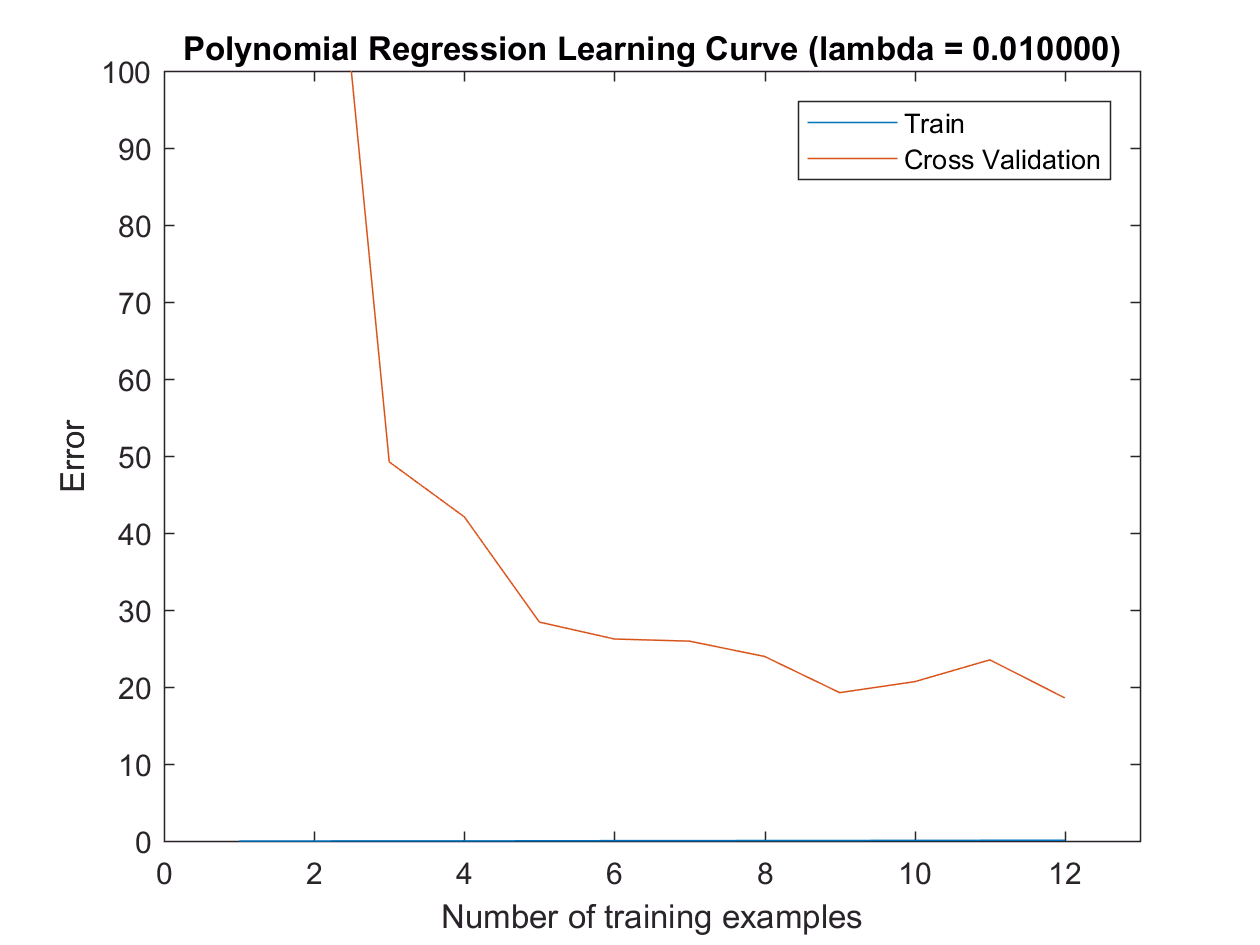

plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')


fprintf('Polynomial Regression (lambda = %f)\n\n', lambda);

Polynomial Regression (lambda = 0.010000)



fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000000	132.603491


  	2		0.004355	149.808648


  	3		0.020733	49.231961


  	4		0.017555	42.095871


  	5		0.027517	28.429750


  	6		0.043707	26.232743


  	7		0.047647	25.953718


  	8		0.062409	23.963069


  	9		0.066782	19.267261


  	10		0.082228	20.694782


  	11		0.090239	23.523432


  	12		0.096042	18.576642



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 8: Validation for Selecting Lambda =============

`You will now implement validationCurve to test various values of `

`lambda on a validation set. You will then use this to select the`

`"best" lambda value.`

[lambda_vec, error_train, error_val] = ...
    validationCurve(X_poly, y, X_poly_val, yval);

close all;
plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');

fprintf('lambda\t\tTrain Error\tValidation Error\n');
for i = 1:length(lambda_vec)
	fprintf(' %f\t%f\t%f\n', ...
            lambda_vec(i), error_train(i), error_val(i));
end

% Find the best lambda (I wrote this code)
[~,bestLambdaPos] = min(error_val);
bestLambda = lambda_vec(bestLambdaPos);
% Train using that lambda
bestTheta = trainLinearReg(X, y, bestLambda);
% Calculate test error
h_test = X_poly_test * theta;
test_error = ((h_test - ytest)' * (h_test - ytest)) / (2 * size(ytest, 1));
fprintf('Test error: %f', test_error);

fprintf('Program paused. Press enter to continue.\n');
pause;